# Motor Test Results and Analysis

Date: 2023-08-17

Author: Jonas Wagner

Test done with a new motor which started at 50rpm and ended in a stall after 3.5ish min.

This is likely due to the higher loading and lower RPM then is ideal for the motor.

Data ingested from 20230817_161823_1.mp4 using dataIngest.m

clear
close all
T = readtable("data\motorTestData_20230817_161823_1.csv","VariableNamingRule","preserve");
T = fillmissing(T,"nearest");
T.omega = (2*pi/60).*T.RPM;
T.P_in_W = T.("Voltage (V)") .* T.("Current (A)");
T.P_out_W = T.("Torque (Nm)") .* T.omega;
T.eta = T.P_out_W ./ T.P_in_W

T = 6118×9 table
    Time (s)    Current (A)    Voltage (V)    Torque (Nm)    RPM    omega     P_in_W    P_out_W      eta  
    ________    ___________    ___________    ___________    ___    ______    ______    _______    _______

    0.33327        0.72           24.89           0.5        51     5.3407    17.921    2.6704     0.14901
    0.36658        0.72           24.89           0.5        51     5.3407    17.921    2.6704     0.14901
     0.3999        0.72           24.89           0.5        51     5.3407    17.921    2.6704     0.14901
    0.43322        0.72           24.89           0.5        51     5.3407    17.921    2.6704     0.14901
    0.46656        0.72           

% Energy (J) = Power (W) * Time (s)
E_total_in = sum(10*T.P_in_W);
E_total_out = sum(10*T.P_out_W);
eta_total = E_total_out/E_total_in;
fprintf('Total Energy In: %0d W\n',round(E_total_in)); fprintf('Total Energy Out: %0d W\n',round(E_total_out)); fprintf('Total Efficiency: %.2f%%',100*eta_total)

Total Energy In: 940771 W
Total Energy Out: 91890 W
Total Efficiency: 9.77%

## Plots

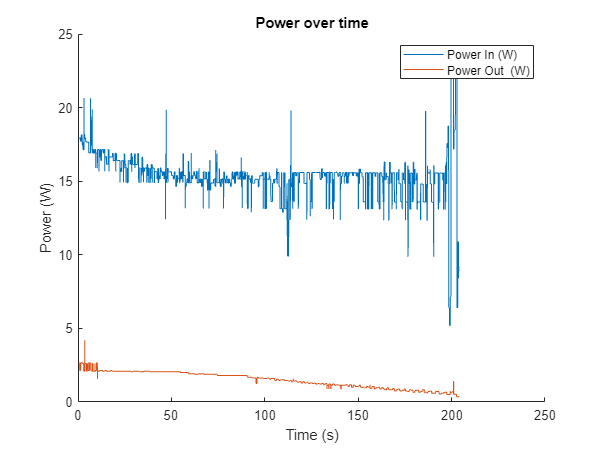

figure
hold on
plot(T.("Time (s)"), T.P_in_W, DisplayName = "Power In (W)")
plot(T.("Time (s)"), T.P_out_W, DisplayName = "Power Out  (W)")
title('Power over time')
xlabel('Time (s)')
ylabel('Power (W)')
legend

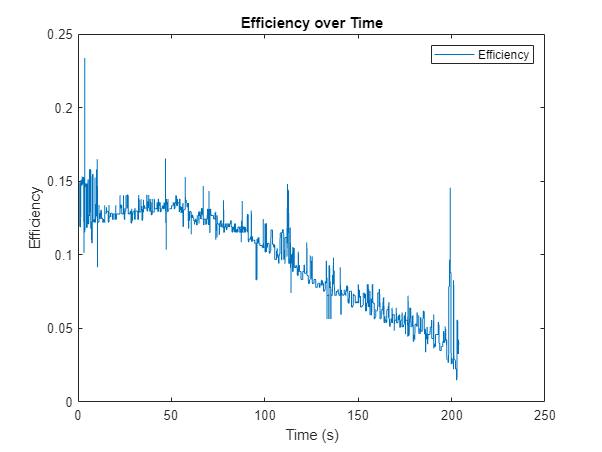

figure
plot(T.("Time (s)"), T.eta, DisplayName="Efficiency")
title('Efficiency over Time')
xlabel('Time (s)')
ylabel('Efficiency')
legend